# Numerischer Rang

Sei $m \geq 4$ gegeben.

m=12;

Wir betrachten die $m\times 3$-Matrix mit Rang 1:

               
$$B=\frac{1}{13}\left(\matrix{ 1 \cr 2 \cr \vdots\cr m}\right) \left(\matrix{1 & 0 & 0}\right)+ \frac{1}{7}\left( \matrix{1 \cr 2 \cr \vdots\cr m}\right)\left(\matrix{ 0 & 1 &0}\right)$$



B = zeros(m,3);
fak=(1:m)';
B(:,1) = (1/13)*fak;
B(:,2) = (1/7)*fak;
format short;
B

B =     0.0769    0.1429         0
    0.1538    0.2857         0
    0.2308    0.4286         0
    0.3077    0.5714         0
    0.3846    0.7143         0
    0.4615    0.8571         0
    0.5385    1.0000         0
    0.6154    1.1429         0
    0.6923    1.2857         0
    0.7692    1.4286         0


Hierzu wird die gestörte $m\times 3$-Matrix

         
$$A=B+\delta_1 \,m^{1.5}\,{\rm eps}\left(\matrix{ 0 \cr 1 \cr 0 \cr \vdots \cr \vdots \cr 0}\right) \left(\matrix{0& 1 & 0}\right)+ \delta_2 \,m^{1.5}\,{\rm eps}\left( \matrix{0 \cr 0 \cr 1\cr 0 \cr \vdots \cr 0}\right)\left(\matrix{ 0 & 0 &1}\right)$$


mit Parametern $\delta_1$, $\delta_2$, definiert.

# Aktivität:

Wählen Sie die Dimension $m$ und verschiedene Parameterwerte $\delta_1, \delta_2$. Sinnvolle Parameterwerte liegen im Intervall $[0,10]$, zum Beispiel (für $m=10$): $(\delta_1,\delta_2) \in \{(1,0),(2,0),2,1),(2,7),(8,7)\}$.

delta1=2;
delta2=0;

e2=zeros(m,1); e2(2)=1;
e3=zeros(m,1); e3(3)=1;
A=B+delta1*m^(1.5)*eps*e2*[0 1 0] + delta2*m^(1.5)*eps*e3*[0 0 1];

Von der Matrix $A$ werden die Singulärwerte bestimmt. Die berechneten Singulärwerte werden mit $\tilde \sigma_i$, $i=1,2,3$, bezeichnet. Die Anzahl der Singulärwerte $\tilde \sigma_i > 0$ wird bestimmt.

format shorte;
S  = svd(A)

S =    4.1366e+00
   8.7371e-15
            0


fprintf('\n Anzahl der strikt positiven Singulärwerte: \n');


 Anzahl der strikt positiven Singulärwerte: 


Anzahl_strikt_pos=sum(S ~= 0)

Anzahl_strikt_pos =      2


Zur Bestimmung des numerischen Ranges der Matrix $A$ nehmen wir das im Buch behandelte Kriterium (Abschnitt 4.6.3 im Buch) und eine Variante davon:

   
$$\min\{ \, k\,| \, \tilde \sigma_{k+1} \leq s_q\,\}, \quad \text{mit}~~s_1:=\tilde \sigma_1 \sqrt{3m} \,\,{\rm eps},~\text{oder}~~s_2:=\tilde \sigma_1 m\, \,{\rm eps} $$
 

(hierbei ist ${\rm eps}$ die Maschinengenauigkeit).  Die Variante mit $s_1$ wird im Buch hergeleitet und die mit $s_2$ entspricht der Rangbestimmung in Matlab. 

fprintf('\n Kritrium 1; Wert der Größe s_1: \n');


 Kritrium 1; Wert der Größe s_1: 


s1=S(1)*sqrt(3*m)*eps

s1 =    5.5111e-15


fprintf('\n Kritrium 2; Wert der Größe s_2: \n');


 Kritrium 2; Wert der Größe s_2: 


s2=S(1)*m*eps

s2 =    1.1022e-14


S(4)=0;
r=3;
while (S(r+1)<=s1)
    r=r-1;
end
Rang1=r+1

Rang1 =      2


r=3;
while (S(r+1)<=s2)
    r=r-1;
end
Rang2=r+1

Rang2 =      1


Die Ergebnisse werden in einer Tabelle aufgenommen.

# Aktivität:

Variieren Sie $\delta_1$, $\delta_2$ und die Dimension $m$ und vergleichen Sie die numerischen Ränge.

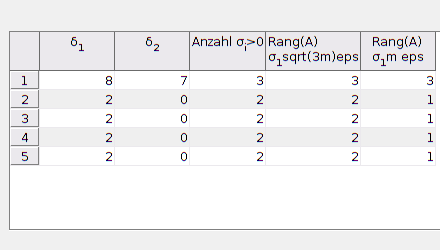

if exist('ErgA','var')<1
    ErgA=[];
end   
clf reset;
f=figure('Position',[ 100 200 450 250]);
axis off;
ErgA=bspmat(delta1,delta2,Rang1,Rang2,Anzahl_strikt_pos,ErgA);

t=uitable(f,'Data',ErgA,'Position',[  10 20 450 200]);
t1=sprintf('<html>δ<sub>1</sub></html>');
t2=sprintf('<html>δ<sub>2</sub></html>');
t3=sprintf('<html>Anzahl σ<sub>i</sub>>0</html>');
t4=sprintf('<html>Rang(A)<br>σ<sub>1</sub>sqrt(3m)<html>eps</html>');
t5=sprintf('<html>Rang(A)<br>σ<sub>1</sub>m <html>eps</html>');
 t.ColumnName = {t1,t2,t3,t4,t5};
hold off;

function ErgA= bspmat(delta1,delta2,Rang1,Rang2,Anzahl_strikt_pos,ErgM)
ErgA=ErgM;
[k n] =size(ErgA);
ErgA(k+1,1) = delta1;
ErgA(k+1,2) = delta2;
ErgA(k+1,3)=  Anzahl_strikt_pos;
ErgA(k+1,4)= Rang1;
ErgA(k+1,5)= Rang2;
end